# ACM 11: Week 2 In-class exercise 2

## Matrix/vector representation of Boundary-value problems

We consider the concentration of pollutant, $u$, in a river section of length $L$. The river flows at speed $a$. The pollutant is leaked from pipes according to the source function $p\left(x\right)$ and the following PDE governs the distribution of pollutant, $u\left(x\right)$:


$$0=-a\frac{\partial u}{\partial x\;}+D\frac{\partial^2 u}{\partial x^2 }+p\left(x\right)$$


The parameters of our problem are given below.

L = 10;     % river length
a = 1;      % river speed
D = 0.1;    % diffusion constant

We start by creating a computational grid of $n+1$ points, and plot the pollutant source function at these grid points.

n = 1000;
x = linspace(0,L,n+1);
x_int = x(2:end-1);      % these are the interior points used for finite differences
dx = x(2)-x(1)

dx = 0.0100

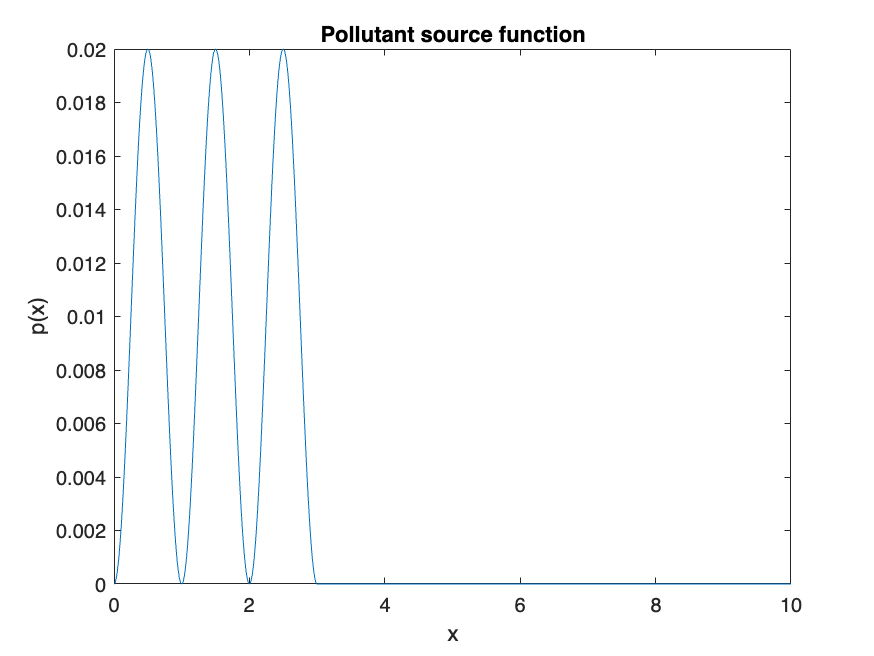


p_src = @(x) 0.01 * (cos(2*pi*x + pi) + 1).* (x<=3);

figure(1); clf
plot(x,p_src(x))
xlabel('x')
ylabel('p(x)')
title('Pollutant source function')

Because our boundary conditions give us $u_0 =u_n =0$, we have $n-1$ unknowns at the interior grid points. Recall that the governing equations are given by


$$0= \left(  - \frac{a}{\Delta x} 
\cdot \textbf A_1 + \frac{D}{(\Delta x)^2}\cdot\textbf A_2 \right)\textbf u + \textbf p$$


where

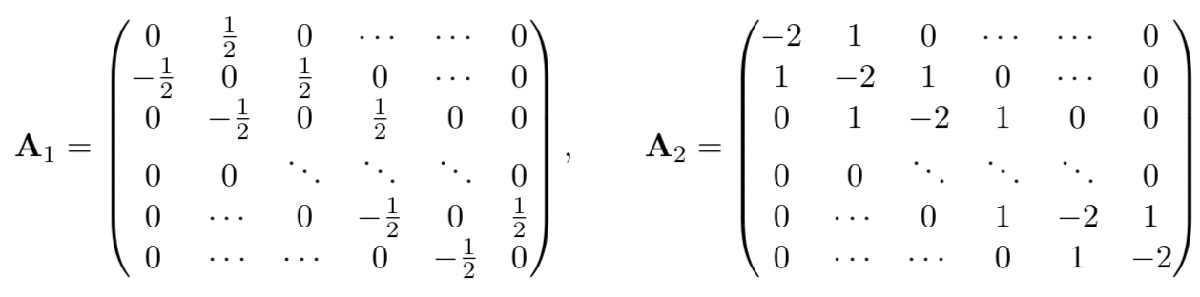

#### (0) Please include all the names of your group members here:

Dallas Taylor

#### (1) Please write some code in the for loop below to fill in the appropriate coefficients of ${\mathit{\mathbf{A}}}_1$ and ${\mathit{\mathbf{A}}}_2$ for the interior equations:

As discussed in class, we can write our difference approximations for $u_x$ and $u_{xx}$ at the grid points as matrices ${\mathit{\mathbf{A}}}_1$ and ${\mathit{\mathbf{A}}}_2$ times the vector $\mathit{\mathbf{u}}$ containing the values of our approximations at the grid points, $u\left(x_i \right)$. We will write some code to build these matrices in the next block.

% initialize all matrices as all zeros
A1 = zeros(n-1);
A2 = zeros(n-1);

% first row
A1(1,2) = 1/2;
A2(1,1:2) = [-2 1];

% loop through rows corresponding to i = 2..n-2 and set the
% coefficients of A1 and A2 appropriately
for i = 2:n-2
    A1(i,i-1:i+1) = [-1/2 0 1/2];
    A2(i,i-1:i+1) = [1 -2 1];
end

% last row
A1(end,end-1) = -1/2;
A2(end,end-1:end) = [1 -2];

#### (2) Now that that's done, we can assemble our overall matrix $\mathit{\mathbf{A}}$ and use MATLAB's backslash command to solve for the steady-state solution:

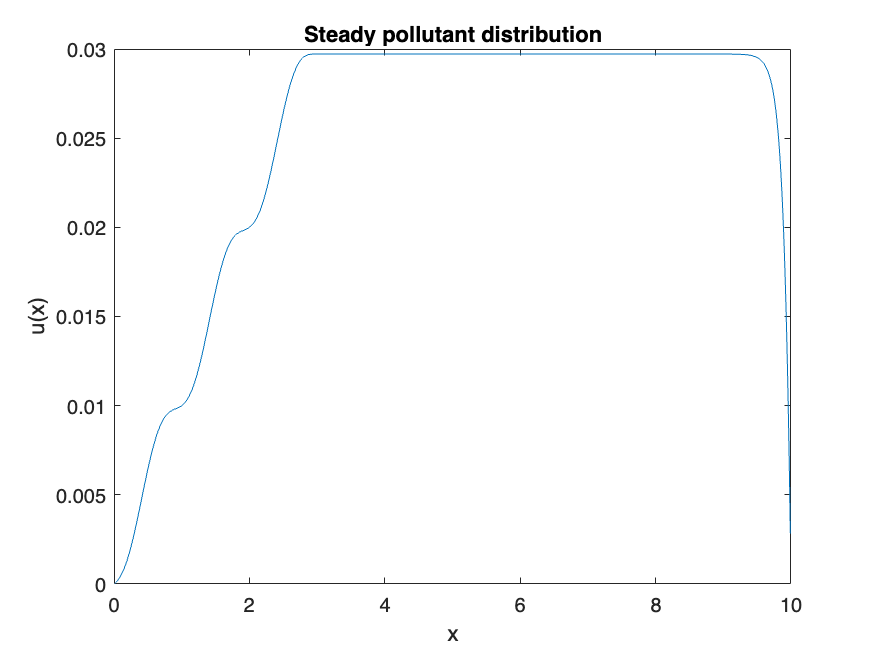

A = -a/dx * A1 + D/dx^2 * A2; % you replace with appropriate A definition here.

p = p_src(x_int');
u = -A\p;

figure(2); clf
plot(x_int,u)
xlabel('x')
ylabel('u(x)')
title('Steady pollutant distribution')

#### (3) Look at the plotted solution: what are its main features? Can you explain these features in terms of the physics represented by the convection, diffusion, and reaction terms?

The main features of the plotted solution are that we have a sort of step like increase from x = 0 to x ~ 3.  There are three steep increases followed by a short step, or by a plateau for the last step at x ~ 3.  This plateau lasts from x ~ 3 to x ~ 9.5, where we then observe an extremely steep decreases that approaches 0 at x ~ 10.   The plateau occurs at u(x) = 0.03, with the two other steps at 0.01 and 0.02.  These features can be explained by the fact that we have a convection constant of -1/0.01 = -100, a diffusion factor of 0.1/(0.01)^2 = 1000 as well as a reaction term that oscillates between 0 and 0.02 then disappears once we reach x > 3.  Thus, we observe the "steps" where our p(x) reaction term is closer to 0, and we observe the plateau once p(x) disappears.